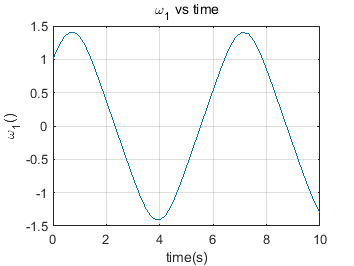

% Parámetros
J1 = 1;
J2 = 2;
J3 = 3;

% Condiciones iniciales
w0 = [1, 1, 1];
tspan = [0, 10];

% Ecuación diferencial
fg=@(t,w)[
    (J3-J2)/J1 * w(2)*w(3);
    (J1-J3)/J2 * w(1)*w(3);
    (J2-J1)/J3 * w(2)*w(1)
];

[t,w]=ode45(fg,tspan,w0);

% Gráficas
plot(t,w(:,1))
grid on
xlabel('time(s)')
ylabel('\omega_1()')  % Añadir unidades
title('\omega_1 vs time', "FontWeight","normal")

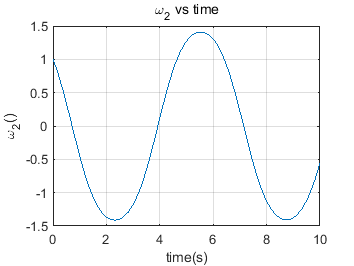


plot(t,w(:,2))
grid on
xlabel('time(s)')
ylabel('\omega_2()')  % Añadir unidades
title('\omega_2 vs time', "FontWeight","normal")

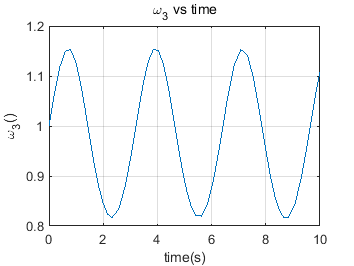


plot(t,w(:,3))
grid on
xlabel('time(s)')
ylabel('\omega_3()')  % Añadir unidades
title('\omega_3 vs time', "FontWeight","normal")